# Lab 5

Marc Eftimie, Raiyan Siddique, Sam Mendelson

clear;

`ex1_inversiontype_biasvoltage_v2voltage_whatsbeingmeasured.mat`

In each:

- Current_M1

- Differential_Voltage = Voltage_Differential

- Voltage_Source_1 (constant)

- foo, smu, ignore

## Current-Voltage Characteristics

dispname = @(t, Vb, V2) t + " for V_b " + string(Vb) + "V, V_2 " + string(V2) + "V";

clf;
hold on;

Vb = 0.7;
Vb_string = "0-7";
V2 = 2.5;
V2_string = "2-5";
load("Ex_1_MI_" + Vb_string + "_" + V2_string + "_I1.mat");
x = Differential_Voltage;
I1 = Current_M1;
load("Ex_1_MI_" + Vb_string + "_" + V2_string + "_I2.mat");
I2 = Current_M1;
load("Ex_1_MI_" + Vb_string + "_" + V2_string + "_VC.mat")
Vc = Voltage_Common;

I_dif = I1'-I2';
xp = x';
f = fit(xp, I_dif, "poly1", "Exclude", (xp < -0.1 | xp > 0.1));

disp(dispname("G_dm = " + string(f.p1), Vb, V2));

G_dm = 5.4284e-05 for V_b 0.7V, V_2 2.5V



plot(x, I1, 'x', 'DisplayName', dispname("I_1", Vb, V2));
plot(x, I2, 'x', 'DisplayName', dispname("I_2", Vb, V2));
plot(x, I1-I2, 'x', 'DisplayName', dispname('I_1-I_2', Vb, V2));
plot(x, I1+I2, 'x', 'DisplayName', dispname('I_1+I_2', Vb, V2));
plot(xp, f.p1*xp + f.p2, 'DisplayName', dispname('I_1-I_2 fit', Vb, V2));

p2x1 = x;
p2y1 = Vc;

Vb = 0.7;
Vb_string = "0-7";
V2 = 3.5;
V2_string = "3-5";
load("Ex_1_MI_" + Vb_string + "_" + V2_string + "_I1.mat");
x = Differential_Voltage;
I1 = Current_M1;
load("Ex_1_MI_" + Vb_string + "_" + V2_string + "_I2.mat");
I2 = Current_M1;
load("Ex_1_MI_" + Vb_string + "_" + V2_string + "_VC.mat")
Vc = Voltage_Common;

I_dif = I1'-I2';
xp = x';
f = fit(xp, I_dif, "poly1", "Exclude", (xp < -0.1 | xp > 0.1));

disp(dispname("G_dm = " + string(f.p1), Vb, V2));

G_dm = 5.5896e-05 for V_b 0.7V, V_2 3.5V



plot(x, I1, 'x', 'DisplayName', dispname("I_1", Vb, V2));
plot(x, I2, 'x', 'DisplayName', dispname("I_2", Vb, V2));
plot(x, I1-I2, 'x', 'DisplayName', dispname('I_1-I_2', Vb, V2));
plot(x, I1+I2, 'x', 'DisplayName', dispname('I_1+I_2', Vb, V2));
plot(xp, f.p1*xp + f.p2, 'DisplayName', dispname('I_1-I_2 fit', Vb, V2));

p2x2 = x;
p2y2 = Vc;

Vb = 0.7;
Vb_string = "0-7";
V2 = 4.5;
V2_string = "4-5";
load("Ex_1_MI_" + Vb_string + "_" + V2_string + "_I1.mat");
x = Differential_Voltage;
I1 = Current_M1;
load("Ex_1_MI_" + Vb_string + "_" + V2_string + "_I2.mat");
I2 = Current_M1;
load("Ex_1_MI_" + Vb_string + "_" + V2_string + "_VC.mat")
Vc = Voltage_Common;

I_dif = I1'-I2';
xp = x';
f = fit(xp, I_dif, "poly1", "Exclude", (xp < -0.1 | xp > 0.1));
disp(dispname("G_dm = " + string(f.p1), Vb, V2));

G_dm = 5.7068e-05 for V_b 0.7V, V_2 4.5V


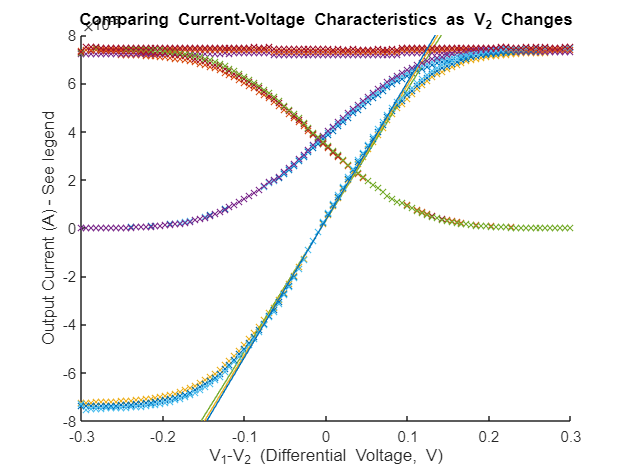


plot(x, I1, 'x', 'DisplayName', dispname("I_1", Vb, V2));
plot(x, I2, 'x', 'DisplayName', dispname("I_2", Vb, V2));
plot(x, I1-I2, 'x', 'DisplayName', dispname('I_1-I_2', Vb, V2));
plot(x, I1+I2, 'x', 'DisplayName', dispname('I_1+I_2', Vb, V2));
plot(xp, f.p1*xp + f.p2, 'DisplayName', dispname('I_1-I_2 fit', Vb, V2));

p2x3 = x;
p2y3 = Vc;

%set(gca, 'xscale', 'log')

%legend("location", "best");
title("Comparing Current-Voltage Characteristics as V_2 Changes");
xlabel("V_1-V_2 (Differential Voltage, V)");
ylabel("Output Current (A) - See legend");
ylim([-8e-6 8e-6]);
hold off;

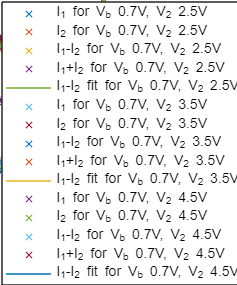

*The legend for the above graph. Since it's so large, it takes up so much space on the actual graph.*

*It's also hard to see the scale of the y-axis as its power of 10 is covered by the title: all numbers on the y-axis should be multiplied by *$10^{-6}$.

The current-voltage characteristics change insignificantly as $V_2$ changes.

$G_{dm}$, the differential-mode transconductance gain, also changes insignificantly: our numbers were 5.4284, 5.5896, and 5.706 ($*10^{-5}$) for 2.5V, 3.5V, and 4.5V $V_2$ values respectively.

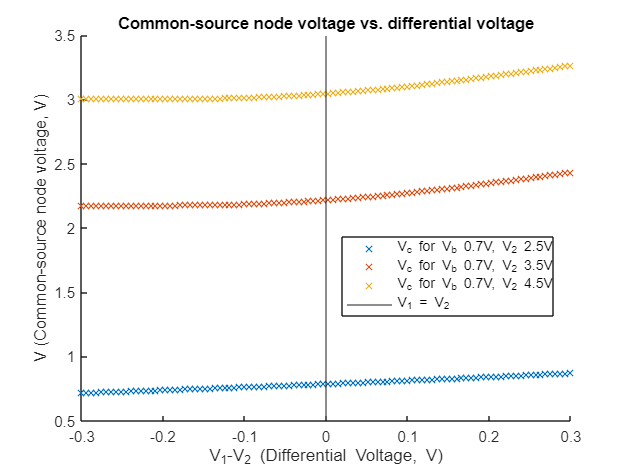

clf;
hold on;
plot(p2x1, p2y1, 'x', 'DisplayName', dispname("V_c", 0.7, 2.5));
plot(p2x2, p2y2, 'x', 'DisplayName', dispname("V_c", 0.7, 3.5));
plot(p2x3, p2y3, 'x', 'DisplayName', dispname("V_c", 0.7, 4.5));
xline(0, 'DisplayName', 'V_1 = V_2')

legend('location', 'best');
xlabel("V_1-V_2 (Differential Voltage, V)");
ylabel("V (Common-source node voltage, V)");
title("Common-source node voltage vs. differential voltage");
hold off;

When $V_1 < V_2$, $V$gains linearly. Once $V_1 > V_2$, $V$ begins to grow exponentially.

## Upper Bias Current

clear;
clf;

dispname = @(t, Vb, V2) t + " for V_b " + string(Vb) + "V, V_2 " + string(V2) + "V";

Vb = 1.6;
Vb_string = "1-6";
V2 = 3.5;
V2_string = "3-5";
load("Ex_1_SI_" + Vb_string + "_" + V2_string + "_I1.mat");
x = Differential_Voltage;
I1 = Current_M1;
load("Ex_1_SI_" + Vb_string + "_" + V2_string + "_I2.mat");
I2 = Current_M1;
load("Ex_1_SI_" + Vb_string + "_" + V2_string + "_VC.mat")
Vc = Voltage_Common;

I_dif = I1'-I2';
xp = x';
f = fit(xp, I_dif, "poly1", "Exclude", (xp < -0.1 | xp > 0.1));

hold on;
disp(dispname("G_dm = " + string(f.p1), Vb, V2));

G_dm = 0.00057527 for V_b 1.6V, V_2 3.5V


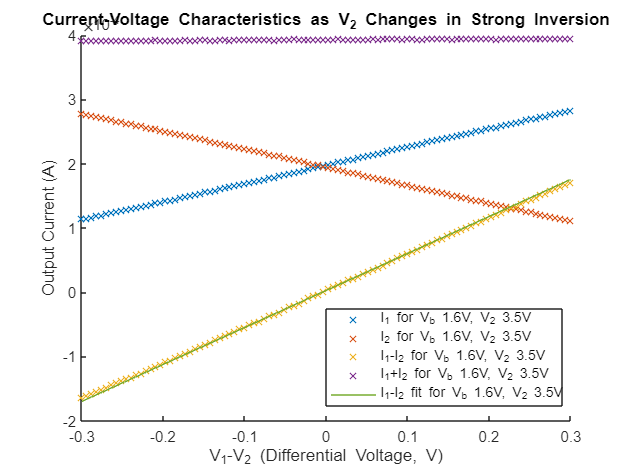


plot(x, I1, 'x', 'DisplayName', dispname("I_1", Vb, V2));
plot(x, I2, 'x', 'DisplayName', dispname("I_2", Vb, V2));
plot(x, I1-I2, 'x', 'DisplayName', dispname('I_1-I_2', Vb, V2));
plot(x, I1+I2, 'x', 'DisplayName', dispname('I_1+I_2', Vb, V2));
plot(xp, f.p1*xp + f.p2, 'DisplayName', dispname('I_1-I_2 fit', Vb, V2));

%set(gca, 'xscale', 'log')

legend("location", "best");
xlabel("V_1-V_2 (Differential Voltage, V)");
ylabel("Output Current (A)");
title("Current-Voltage Characteristics as V_2 Changes in Strong Inversion")

hold off;

The Current-Voltage relationship is much more linear in strong inversion than weak inversion.